# MPC control with CasADi & CarSim

## read the path

first we need to read the path of the car

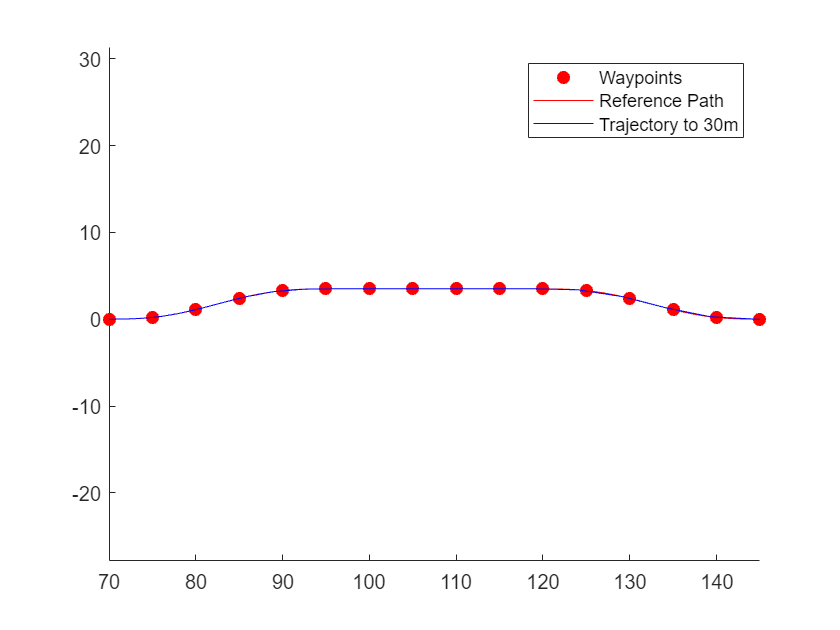

path_table = readtable('maps.csv');
path = path_table{:,:};

waypoints = path;
refPath = referencePathFrenet(waypoints);
connector = trajectoryGeneratorFrenet(refPath);
initState = [0 0 0 0 0 0];  % [S ds ddS L dL ddL]
termState = [140 0 0 0 0 0]; % [S ds ddS L dL ddL]
[~,trajGlobal] = connect(connector,initState,termState,5);
show(refPath);
hold on
axis equal
plot(trajGlobal.Trajectory(:,1),trajGlobal.Trajectory(:,2),'b')
legend(["Waypoints","Reference Path","Trajectory to 30m"])


ref_path = [trajGlobal.Trajectory(:,1) trajGlobal.Trajectory(:,2)]

ref_path =    70.0000         0
   70.0109    0.0001
   70.0843    0.0008
   70.2758    0.0026
   70.6335    0.0063
   71.1983    0.0134
   72.0044    0.0288
   73.0792    0.0647
   74.4427    0.1490
   76.1050    0.3339


current_point = [100 2];
closest_point = dsearchn(path_discrete,current_point)

closest_point = 18